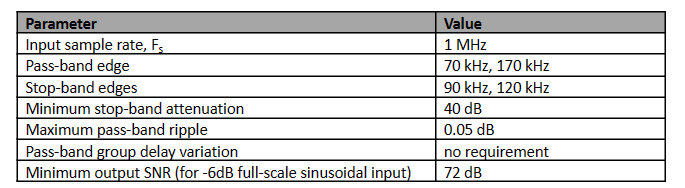

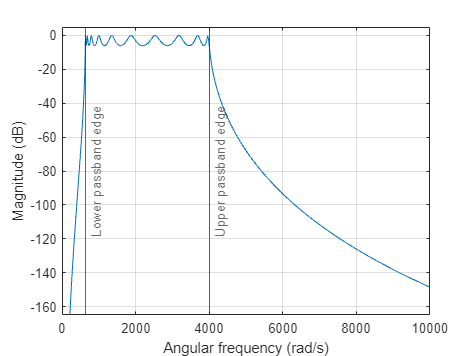

[z,p,k] = cheb1ap(10,6);
[A,B,C,D] = zp2ss(z,p,k); 
fs = 1e6;

f1 = 100; u1 = 2*fs*tan(f1*(2*pi/fs)/2);
f2 = 500; u2 = 2*fs*tan(f2*(2*pi/fs)/2);

[At,Bt,Ct,Dt] = lp2bp(A,B,C,D,sqrt(u1*u2),u2-u1);

[b,a] = ss2tf(At,Bt,Ct,Dt);
[h,w] = freqs(b,a,2048);

plot(w,mag2db(abs(h)))
xline([u1 u2],"-",["Lower" "Upper"]+" passband edge", ...
    LabelVerticalAlignment="middle")

ylim([-165 5])
xlabel("Angular frequency (rad/s)")
ylabel("Magnitude (dB)")
grid

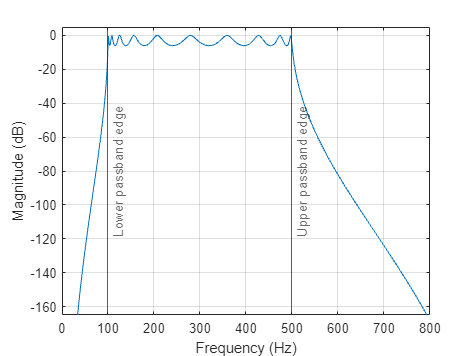


[Ad,Bd,Cd,Dd] = bilinear(At,Bt,Ct,Dt,fs);

[hd,fd] = freqz(ss2sos(Ad,Bd,Cd,Dd),2048,fs);

plot(fd,mag2db(abs(hd)))
xline([f1 f2],"-",["Lower" "Upper"]+" passband edge", ...
    LabelVerticalAlignment="middle")

ylim([-165 5])
xlabel("Frequency (Hz)")
ylabel("Magnitude (dB)")
grid


% [num,den,allpassNum,allpassDen] = iirlp2bs(b,a,wo,wt)